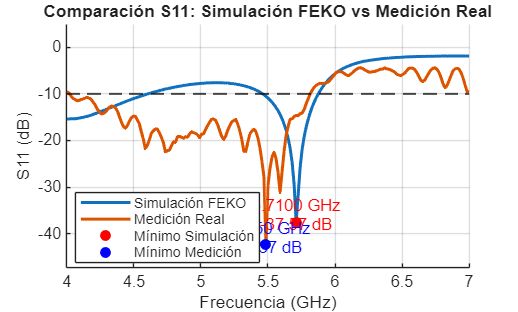

clc; clear; close all;

%% ============================
%     1) SIMULACIÓN (FEKO)
% ============================
data = sparameters('antenadatos.s1p');

freq_sim = data.Frequencies(:);            
S11_sim  = squeeze(data.Parameters(1,1,:));
S11_sim_dB = 20*log10(abs(S11_sim));

% Mínimo simulación
[min_sim, idx_min_sim] = min(S11_sim_dB);
fmin_sim_GHz = freq_sim(idx_min_sim)/1e9;


%% ============================
%     2) MEDICIÓN REAL (CSV)
% ============================
HeaderLines = 13;
fileAmp = 'CSV4.csv';
A = readmatrix(fileAmp, 'NumHeaderLines', HeaderLines);

freq_meas = A(:,1);       
meas_dB = A(:,2);

% Mínimo medición
[min_meas, idx_min_meas] = min(meas_dB);
fmin_meas_GHz = freq_meas(idx_min_meas)/1e9;


%% ============================
%           3) GRAFICAR
% ============================
figure; hold on; grid on;

% Simulación
plot(freq_sim/1e9, S11_sim_dB, 'LineWidth', 1.8);

% Medición real
plot(freq_meas/1e9, meas_dB, 'LineWidth', 1.8);

% Línea -10 dB (sin leyenda)
yline(-10, '--k', 'LineWidth', 1.2, 'HandleVisibility', 'off');

% Punto mínimo simulación
plot(fmin_sim_GHz, min_sim, 'ro', 'MarkerFaceColor','r');
text(fmin_sim_GHz, min_sim + 1.5, ...
    sprintf('%.4f GHz\n%.2f dB', fmin_sim_GHz, min_sim), ...
    'HorizontalAlignment','center', 'Color','r');

% Punto mínimo medición
plot(fmin_meas_GHz, min_meas, 'bo', 'MarkerFaceColor','b');
text(fmin_meas_GHz, min_meas + 1.5, ...
    sprintf('%.4f GHz\n%.2f dB', fmin_meas_GHz, min_meas), ...
    'HorizontalAlignment','center', 'Color','b');


%% ============================
%         FORMATO FINAL
% ============================
xlabel('Frecuencia (GHz)');
ylabel('S11 (dB)');
title('Comparación S11: Simulación FEKO vs Medición Real');

legend('Simulación FEKO', ...
       'Medición Real', ...
       'Mínimo Simulación', ...
       'Mínimo Medición', ...
       'Location','best');

ylim([min([S11_sim_dB; meas_dB]) - 5, 5]);